# **DERS - 5**

### 2-Boyutlu Grafik Çizdirme

MATLAB'de gerçekleştirilen neredeyse tüm projelerde, elde edilen sonuçları görmek için grafikler oluşturulur. Örneğin

- Matematiksel fonksiyonları,

- Rastlantı değişkenlerinin olasılık yoğunluk fonksiyonlarını,

- Bir sensörden toplanan verilerin nasıl dağıldığını,

- Herhangi bir değişkenin başka bir değişkene göre nasıl değiştiğini,

ve daha birçok merak edileni gözlemlemek için grafikler oldukça sık kullanılırlar. MATLAB'de grafik çizdirmek için kulanılan en temel fonksiyon `plot` fonksiyonudur. Örneğin, Stephen Curry'nin kariyeri boyunca her sezon attığı üçlüklerin grafiği aşağıdaki gibi elde edilebilir.

seasons = 1 : 14;
three_points_made = [166, 151, 55, 272, 261, 286, 402, 324, 212, 354, 12, 337, 285, 273];
plot(seasons, three_points_made);

Grafiğin arka planını ızgara biçiminde yapmak grafiği ve verileri gözlemlemeyi kolaylaştırır. Bunun için `grid` fonksiyonu kullanılabilir.

seasons = 1 : 14;
three_points_made = [166, 151, 55, 272, 261, 286, 402, 324, 212, 354, 12, 337, 285, 273];
plot(seasons, three_points_made);
grid;

Eksenlerin değer aralıklarını iyi ayarlamak gerekir, yoksa veriler doğru gözlemlenemez. Örneğin Curry'nin üçlük sayıları 12 ile 402 aralığında olduğu için, grafiğin -10000 ile 10000 aralığında incelenmesi yanıltıcı olabilir. Sanki her yıl neredeyse aynı sayıda üçlük atıyormuş gibi bir algı oluşturabilir ve yanlış yorumlamaya sebebiyet verebilir. Eksenlerin minimum ve maksimum değerleri farklı şekillerde ayarlanabilir. Bunun için ilk olarak `axis` fonksiyonu kullanılabilir.

seasons = 1 : 14;
three_points_made = [166, 151, 55, 272, 261, 286, 402, 324, 212, 354, 12, 337, 285, 273];
plot(seasons, three_points_made);
axis([1 14 0 450]);
grid;

Eksenlerin minimum ve maksimum değerleri aynı zamanda `xlim` ve `ylim` fonksiyonları kullanılarak da ayarlanabilir.

seasons = 1 : 14;
three_points_made = [166, 151, 55, 272, 261, 286, 402, 324, 212, 354, 12, 337, 285, 273];
plot(seasons, three_points_made);
xlim([1, 14]);
ylim([0, 450]);
grid;

Eksenlerdeki değerlerin aralıkları da `xticks` ve `yticks` fonksiyonları kullanılarak ayarlanabilir.

seasons = 1 : 14;
three_points_made = [166, 151, 55, 272, 261, 286, 402, 324, 212, 354, 12, 337, 285, 273];
plot(seasons, three_points_made);
xlim([1, 14]);
ylim([0, 450]);
xticks(1 : 14);
grid;

Eksenlerdeki sayı değerleri yerine yazılar da gösterilebilir. Bunun için `xticklabels` ve `yticklabels` fonksiyonları kullanılabilir.

seasons = 1 : 14;
three_points_made = [166, 151, 55, 272, 261, 286, 402, 324, 212, 354, 12, 337, 285, 273];
plot(seasons, three_points_made);
xlim([1, 14]);
ylim([0, 450]);
xticks(1 : 14);
xticklabels(["9/10", "10/11", "11/12", "12/13", "13/14", "14/15", "15/16", ...
             "16/17", "17/18", "18/19", "19/20", "20/21", "21/22", "22/23"]);
grid;

Eksenleri isimlendirmek elde edilen grafiği anlamlandırmak adına oldukça önemlidir. Burada x-ekseninin hangi değişkeni temsil ettiğini göstermek için `xlabel` fonksiyonu kullanılırken, y-ekseninin hangi değişkeni temsil ettiğini göstermek için de `ylabel` fonksiyonu kullanılır. Grafiğe başlık koyabilmek için de `title` fonksiyonu kullanılır.

Yunan alfabesi değişken tanımlamalarında sıkça kullanıldığı için grafiklere eklenmesi gerekebilir. Hangi harfin nasıl yazılacağı MathWorks sitesinde detaylı bir tablo olarak verilmiştir:

- Yunan Alfabesi: [https://www.mathworks.com/help/matlab/creating_plots/greek-letters-and-special-characters-in-graph-text.html](https://www.mathworks.com/help/matlab/creating_plots/greek-letters-and-special-characters-in-graph-text.html)

seasons = 1 : 14;
three_points_made = [166, 151, 55, 272, 261, 286, 402, 324, 212, 354, 12, 337, 285, 273];
plot(seasons, three_points_made);
title("3pt Statistics");
xlabel("Season");
ylabel("3pt Made");
xlim([1, 14]);
ylim([0, 450]);
xticks(1 : 14);
xticklabels(["9/10", "10/11", "11/12", "12/13", "13/14", "14/15", "15/16", ...
             "16/17", "17/18", "18/19", "19/20", "20/21", "21/22", "22/23"]);
grid;

Eksenlerdeki yazıların boyutları, tipleri ve renkleri de isteğe göre değiştirilebilir. Bunun için de kod aşağıdaki gibi düzenlenebilir.

seasons = 1 : 14;
three_points_made = [166, 151, 55, 272, 261, 286, 402, 324, 212, 354, 12, 337, 285, 273];
plot(seasons, three_points_made);
title("3pt Statistics");
xlabel("Season", "FontSize", 20, "FontWeight", "bold", "Color", "r", "Interpreter", "latex");
ylabel("3pt Made");
xlim([1, 14]);
ylim([0, 450]);
xticks(1 : 14);
xticklabels(["9/10", "10/11", "11/12", "12/13", "13/14", "14/15", "15/16", ...
             "16/17", "17/18", "18/19", "19/20", "20/21", "21/22", "22/23"]);
grid;

MATLAB'de bazı harfler hazır olarak bazı renkler için tanımlanmıştır:

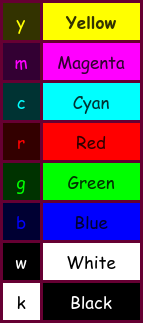              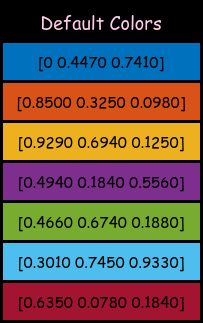

Ancak bunlar haricinde de RGB renk kodları ile istenen renk elde edilebilir.

seasons = 1 : 14;
three_points_made = [166, 151, 55, 272, 261, 286, 402, 324, 212, 354, 12, 337, 285, 273];
plot(seasons, three_points_made, "Color", [0.8500 0.3250 0.0980]);
title("3pt Statistics", "FontSize", 15, "Interpreter", "latex");
xlabel("Season", "FontSize", 15, "Interpreter", "latex");
ylabel("3pt Made", "FontSize", 15, "Interpreter", "latex");
xlim([1, 14]);
ylim([0, 450]);
xticks(1 : 14);
xticklabels(["9/10", "10/11", "11/12", "12/13", "13/14", "14/15", "15/16", ...
             "16/17", "17/18", "18/19", "19/20", "20/21", "21/22", "22/23"]);
grid;

Grafiğin kalınlığı da isteğe göre ayarlanabilir.

seasons = 1 : 14;
three_points_made = [166, 151, 55, 272, 261, 286, 402, 324, 212, 354, 12, 337, 285, 273];
plot(seasons, three_points_made, "Color", [0.8500 0.3250 0.0980], ...
                                 "LineWidth", 2);
title("3pt Statistics", "FontSize", 15, "Interpreter", "latex");
xlabel("Year", "FontSize", 15, "Interpreter", "latex");
ylabel("3pt Made", "FontSize", 15, "Interpreter", "latex");
xlim([1, 14]);
ylim([0, 450]);
xticks(1 : 14);
xticklabels(["9/10", "10/11", "11/12", "12/13", "13/14", "14/15", "15/16", ...
             "16/17", "17/18", "18/19", "19/20", "20/21", "21/22", "22/23"]);
grid;

Grafik sadece düz çizgi şeklinde olmak zorunda değildir, isteğe göre değiştirilebilir.

seasons = 1 : 14;
three_points_made = [166, 151, 55, 272, 261, 286, 402, 324, 212, 354, 12, 337, 285, 273];
plot(seasons, three_points_made, "--o", ...
                                 "Color", [0.8500 0.3250 0.0980], ...
                                 "LineWidth", 2);
title("3pt Statistics", "FontSize", 15, "Interpreter", "latex");
xlabel("Year", "FontSize", 15, "Interpreter", "latex");
ylabel("3pt Made", "FontSize", 15, "Interpreter", "latex");
xlim([1, 14]);
ylim([0, 450]);
xticks(1 : 14);
xticklabels(["9/10", "10/11", "11/12", "12/13", "13/14", "14/15", "15/16", ...
             "16/17", "17/18", "18/19", "19/20", "20/21", "21/22", "22/23"]);
grid;

Grafiğin kalınlığı ve rengi değiştirilmeden sadece verilerin gösterildiği şekillerin kalınlığı ve rengi de değiştirilebilir.

seasons = 1 : 14;
three_points_made = [166, 151, 55, 272, 261, 286, 402, 324, 212, 354, 12, 337, 285, 273];
plot(seasons, three_points_made, "o--", ...
                                 "Color", [0.8500 0.3250 0.0980], ...
                                 "LineWidth", 2, ...
                                 "MarkerEdgeColor", [0.8500 0.3250 0.0980], ...
                                 "MarkerFaceColor", [0.8500 0.3250 0.0980], ...
                                 "MarkerSize", 10);
title("3pt Statistics", "FontSize", 15, "Interpreter", "latex");
xlabel("Year", "FontSize", 15, "Interpreter", "latex");
ylabel("3pt Made", "FontSize", 15, "Interpreter", "latex");
xlim([1, 14]);
ylim([0, 450]);
xticks(1 : 14);
xticklabels(["9/10", "10/11", "11/12", "12/13", "13/14", "14/15", "15/16", ...
             "16/17", "17/18", "18/19", "19/20", "20/21", "21/22", "22/23"]);
grid;

Birden fazla veri aynı grafik üzerinde gözlemlenebilir. Bunun için `hold on` fonksiyonu kullanılabilir. Tüm çizim kodları tamamlandıktan sonra da `hold off` fonksiyonu ile çizimin bittiği bildirilmelidir ki sonraki çizimler de bu grafik üzerinde çıkmasın. Örneğin hem Stephen Curry hem de Klay Thompson'ın üçlük istatistikleri aynı grafik üzerinde aşağıdaki gibi gösterilebilir.

seasons = 1 : 14;
stephen_curry = [166, 151, 55, 272, 261, 286, 402, 324, 212, 354, 12, 337, 285, 273];
klay_thompson = [111, 211, 223, 239, 276, 268, 229, 241, 0, 0, 114, 301];

plot(seasons, stephen_curry, "o--", ...
                             "Color", [0.8500 0.3250 0.0980], ...
                             "LineWidth", 2, ...
                             "MarkerEdgeColor", [0.8500 0.3250 0.0980], ...
                             "MarkerFaceColor", [0.8500 0.3250 0.0980], ...
                             "MarkerSize", 10);
hold on;
plot(seasons(3 : end), klay_thompson, "o--", ...
                                      "Color", [0.3010 0.7450 0.9330], ...
                                      "LineWidth", 2, ...
                                      "MarkerEdgeColor", [0.3010 0.7450 0.9330], ...
                                      "MarkerFaceColor", [0.3010 0.7450 0.9330], ...
                                      "MarkerSize", 10);
hold off;

title("3pt Statistics", "FontSize", 15, "Interpreter", "latex");
xlabel("Year", "FontSize", 15, "Interpreter", "latex");
ylabel("3pt Made", "FontSize", 15, "Interpreter", "latex");
xlim([1, 14]);
ylim([0, 450]);
xticks(1 : 14);
xticklabels(["9/10", "10/11", "11/12", "12/13", "13/14", "14/15", "15/16", ...
             "16/17", "17/18", "18/19", "19/20", "20/21", "21/22", "22/23"]);
grid;

Birden fazla veri aynı grafik üzerinde gösterilirken karışıklık olmaması açısından verileri tanımlamak gerekir. Bunun için de `legend` fonksiyonu kullanılır.

seasons = 1 : 14;
stephen_curry = [166, 151, 55, 272, 261, 286, 402, 324, 212, 354, 12, 337, 285, 273];
klay_thompson = [111, 211, 223, 239, 276, 268, 229, 241, 0, 0, 114, 301];

plot(seasons, stephen_curry, "o--", ...
                             "Color", [0.8500 0.3250 0.0980], ...
                             "LineWidth", 2, ...
                             "MarkerEdgeColor", [0.8500 0.3250 0.0980], ...
                             "MarkerFaceColor", [0.8500 0.3250 0.0980], ...
                             "MarkerSize", 10);
hold on;
plot(seasons(3 : end), klay_thompson, "o--", ...
                                      "Color", [0.3010 0.7450 0.9330], ...
                                      "LineWidth", 2, ...
                                      "MarkerEdgeColor", [0.3010 0.7450 0.9330], ...
                                      "MarkerFaceColor", [0.3010 0.7450 0.9330], ...
                                      "MarkerSize", 10);
hold off;

title("3pt Statistics", "FontSize", 15, "Interpreter", "latex");
xlabel("Year", "FontSize", 15, "Interpreter", "latex");
ylabel("3pt Made", "FontSize", 15, "Interpreter", "latex");
legend("Stephen Curry", "Klay Thompson", "FontSize", 12, "Interpreter", "latex")
xlim([1, 14]);
ylim([0, 500]);
xticks(1 : 14);
xticklabels(["9/10", "10/11", "11/12", "12/13", "13/14", "14/15", "15/16", ...
             "16/17", "17/18", "18/19", "19/20", "20/21", "21/22", "22/23"]);
grid;

Figürün ekrandaki konumu ve boyutları da değiştirilebilir. Bunun için `figure` fonksiyonu kullanılabilir. Son durumda elde edilen figür ilk haliyle karşılaştırıldığında, şimdiye kadar öğrenilen özelliklerin ne kadar büyük bir fark oluşturduğu açıkça görülebilir.

figure("Position", [100 100 800 400]);
seasons = 1 : 14;
stephen_curry = [166, 151, 55, 272, 261, 286, 402, 324, 212, 354, 12, 337, 285, 273];
klay_thompson = [111, 211, 223, 239, 276, 268, 229, 241, 0, 0, 114, 301];

plot(seasons, stephen_curry, "o--", ...
                             "Color", [0.8500 0.3250 0.0980], ...
                             "LineWidth", 2, ...
                             "MarkerEdgeColor", [0.8500 0.3250 0.0980], ...
                             "MarkerFaceColor", [0.8500 0.3250 0.0980], ...
                             "MarkerSize", 10);
hold on;
plot(seasons(3 : end), klay_thompson, "o--", ...
                                      "Color", [0.3010 0.7450 0.9330], ...
                                      "LineWidth", 2, ...
                                      "MarkerEdgeColor", [0.3010 0.7450 0.9330], ...
                                      "MarkerFaceColor", [0.3010 0.7450 0.9330], ...
                                      "MarkerSize", 10);
hold off;

title("3pt Statistics", "FontSize", 15, "Interpreter", "latex");
xlabel("Year", "FontSize", 15, "Interpreter", "latex");
ylabel("3pt Made", "FontSize", 15, "Interpreter", "latex");
legend("Stephen Curry", "Klay Thompson", "FontSize", 12, "Interpreter", "latex")
xlim([1, 14]);
ylim([0, 500]);
xticks(1 : 14);
xticklabels(["9/10", "10/11", "11/12", "12/13", "13/14", "14/15", "15/16", ...
             "16/17", "17/18", "18/19", "19/20", "20/21", "21/22", "22/23"]);
grid;

figure();
seasons = 1 : 14;
three_points_made = [166, 151, 55, 272, 261, 286, 402, 324, 212, 354, 12, 337, 285, 273];
plot(seasons, three_points_made);

Birden fazla veriyi ayrık grafiklerde ancak tek bir figür olarak göstermek için `subplot` fonksiyonu kullanılabilir.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
cos_wave = cos(theta);

x = -10 : 10;
square_x = x.^2;
cube_x = x.^3;

subplot(2, 2, 1);
plot(theta, sine_wave, "LineWidth", 2,...
                       "Color", [0.9290 0.6940 0.1250]);
title("Sinüs");
xlabel("\theta (rad)");
ylabel("Fonksiyon");
grid;

subplot(2, 2, 2);
plot(theta, cos_wave, "LineWidth", 2,...
                      "Color", [0 0.4470 0.7410]);
title("Kosinüs");
xlabel("\theta (rad)");
ylabel("Fonksiyon");
grid;

subplot(2, 2, 3);
plot(x, square_x, "--",...  
                  "LineWidth", 2,...
                  "Color", [0.4660 0.6740 0.1880]);
title("x^{2}");
xlabel("x");
ylabel("Fonksiyon");
grid;

subplot(2, 2, 4);
plot(x, cube_x, "-.",...  
                "LineWidth", 2,...
                "Color", [0.4940 0.1840 0.5560]);
title("x^{3}");
xlabel("x");
ylabel("Fonksiyon");
grid;

MATLAB Live Script kapsamında yazılan programlara interaktif kontroller eklenebilir. Bunun için **LIVE EDITOR **sekmesinde **Control **kısmından istenen interaktif kontrol eklenebilir. Örneğin Gibbs teoremi interaktif bir slider ile çalıştırılabilir. Gibbs teoremine göre çok sayıda sinüs fonksiyonu aşağıda verilen formatta toplanırsa kare fonksiyon elde edilebilir:


$$\text{square}(x,n) = \text{sin}(x) + \frac{1}{3}\text{sin}(3x) + \frac{1}{5}\text{sin}(5x) + \dots + \frac{1}{n}\text{sin}(nx)$$
 

İnteraktif slider sayesinde değişen $n$ değerleri için sinüs fonksiyonlarının kare fonksiyona ne kadar yaklaştığı dinamik olarak gözlemlenebilir.

n = 100;
x = 0 : 1e-5 : 2 * pi;
square_wave = SquareWave(x, n);
plot(x, square_wave, "-",...
                     "LineWidth", 1.5,...
                     "Color", [0.6350 0.0780 0.1840]);
title_string = strcat(string(n), ". Degree Sum");
title(title_string);
xlabel("x");
ylabel("Sum of Sine Waves");
grid;

Plot komutuna alternatif olarak başka çizdirme fonksiyonları da vardır. Eğer y-ekseni logaritmik olarak çizdirilmek istenirse `semilogy` fonksiyonu kullanılabilir.

x = [1e-6 1e-5 1e-4 1e-3 1e-2 1e-1 1 1e1 1e2 1e3 1e4 1e5];

figure;
subplot(1, 2, 1);
plot(x, "-o", "LineWidth", 1.5,...
              "Color", [0.8500 0.3250 0.0980],...
              "MarkerSize", 8,...
              "MarkerFaceColor", [0.8500 0.3250 0.0980]);
title("PLOT");
grid;

subplot(1, 2, 2);
semilogy(x, "-o", "LineWidth", 1.5,...
                  "Color", [0.3010 0.7450 0.9330],...
                  "MarkerSize", 8,...
                  "MarkerFaceColor", [0.3010 0.7450 0.9330]);
title("SEMILOGY");
grid;

Ayrık fonksiyonları göstermek için `stem` fonksiyonu kullanılabilir.

figure;
days = 1 : 48;
temperatures = [19, 16, 16, 20, 21, 22, ...
                20, 22, 32, 25, 23, 16, 19, ...
                22, 27, 21, 23, 27, 28, 32, ...
                24, 24, 22, 22, 25, 23, 20, ...
                24, 27, 30, 24, 22, 25, 23, ...
                20, 26, 29, 23, 24, 25, 25, ...
                28, 34, 33, 22, 26, 23, 24];
stem(days, temperatures, "-o", "LineWidth", 1.5,...
                               "Color", [179, 48, 48] / 255,...
                               "MarkerSize", 8,...
                               "MarkerFaceColor", [245, 176, 95] / 255);
xlabel("Days");
ylabel("Temperature");
grid;

Histogram çizdirmek için `histogram` fonksiyonu kullanılabilir. Histogram, bir vektörü eşit aralıklara böler ve her bir aralıkta kaçar tane eleman olduğunu gösterir. Aslında vektörün dağılımını verir.

% Uniform distribution between 0 and 1.
uni_vec = rand(1, 1e5);
histogram(uni_vec);
grid;

% Uniform distribution of integers between 1 and 5
uni_int_vec = randi([1, 5], [1, 1e5]);
histogram(uni_int_vec, "Normalization", "pdf");
grid;

% Gaussian distribution with means -4, -2, 0, 2, and 4
gaussian_vec = randn(1, 1e5) - 4;
histogram(gaussian_vec, "Normalization", "pdf");
hold on;

gaussian_vec = randn(1, 1e5) - 2;
histogram(gaussian_vec, "Normalization", "pdf");
hold on;

gaussian_vec = randn(1, 1e5);
histogram(gaussian_vec, "Normalization", "pdf");
hold on;

gaussian_vec = randn(1, 1e5) + 2;
histogram(gaussian_vec, "Normalization", "pdf");
hold on;

gaussian_vec = randn(1, 1e5) + 4;
histogram(gaussian_vec, "Normalization", "pdf");
grid;

Bar grafiği çizdirmek için de `bar` fonksiyonu kullanılabilir.

real_madrid_edge = [0, 82, 159] / 255;
real_madrid_face = [254, 190, 16] / 255;
milan_edge = [251, 9, 11] / 255;
milan_face = [0, 0, 0] / 255;
bayern_munich_edge = [0, 102, 178] / 255;
bayern_munich_face = [220, 5, 45] / 255;
liverpool_edge = [0, 178, 169] / 255;
liverpool_face = [200, 16, 46] / 255;
barcelona_edge = [168, 19, 62] / 255;
barcelona_face = [0, 77, 152] / 255;
ajax_edge = [210, 18, 46] / 255;
ajax_face = [255, 255, 255] / 255;

face_color_matrix = [real_madrid_face; milan_face; bayern_munich_face; ...
                     liverpool_face; barcelona_face; ajax_face];
edge_color_matrix = [real_madrid_edge; milan_edge; bayern_munich_edge; ...
                     liverpool_edge; barcelona_edge; ajax_edge];

figure("Position", [100 100 1300 800]);
x = categorical(["Real Madrid", "Milan", "Bayern Munich", ...
                 "Liverpool", "Barcelona", "Ajax"]);
x = reordercats(x, ["Real Madrid", "Milan", "Bayern Munich", ...
                    "Liverpool", "Barcelona", "Ajax"]);
y = [15, 7, 6, 6, 5, 4];
for team_index = 1 : 6
    b = bar(x(team_index), y(team_index), 0.5);
    b.FaceColor = face_color_matrix(team_index, :);
    b.EdgeColor = edge_color_matrix(team_index, :);
    b.LineWidth = 2;
    xtips = b.XEndPoints;
    ytips = b.YEndPoints;
    labels = string(b.YData);
    text(xtips, ytips, labels, "HorizontalAlignment", "center", "VerticalAlignment",...
    "bottom", "FontSize", 20, "Interpreter", "latex");
    hold on;
end
set(gca, "TickLabelInterpreter", "latex");
set(gca, "FontSize" , 20)
title("Champions League Titles", "Interpreter", "latex");
xlabel("Teams", "Interpreter", "latex");
ylabel("Number of Titles", "Interpreter", "latex");
ylim([0 18]);
grid;

### 3-Boyutlu Grafik Çizdirme

İki değişkene bağlı olan fonksiyonların grafiklerini incelemek ve bazı üç boyutlu modellemeleri gerçekleştirmek için üç boyutlu grafikler gerekmektedir. Üç boyutlu grafikleri elde etmek için öncelikle `meshgrid` fonksiyonu kullanılmalıdır. Bu fonksiyon iki adet matris oluşturur:

- Her satırında $x$ vektörünü (birinci bağımsız değişken) içeren bir **X **matrisi

- Her sütununda $y$ vektörünü (ikinci bağımsız değişken) içeren bir **Y** matrisi

x = 1 : 4;
y = 2 : 4 : 18;
[X, Y] = meshgrid(x, y);

Sonra bu matrisler kullanılarak $x$ ve $y$ değişkenlerine bağlı olan bağımsız değişken `surf` fonksiyonu ile çizdirilir. Örneğin $f(x,y) = xe^{-x^{2}-y^{2}}$ fonksiyonu, $x \in [-2, 2]$ ve $y \in [-4, 4]$ aralıkları için üç boyutlu olarak aşağıdaki gibi çizdirilebilir.

x = -2 : 0.15 : 2;
y = -4 : 0.15 : 4;

[X, Y] = meshgrid(x, y);
Z = X .* exp(-X.^2 - Y.^2);
surf(X, Y, Z);
xlabel("x");
ylabel("y");
zlabel("z");

Üç boyutlu çizim haritadaki farklı değerler için farklı renkler almaktadır. Bu renk skalası `colormap` fonksiyonu kullanılarak değiştirilebilir.

x = -2 : 0.15 : 2;
y = -4 : 0.15 : 4;

[X, Y] = meshgrid(x, y);
Z = X .* exp(-X.^2 - Y.^2);
surf(X, Y, Z);
colormap(prism);
xlabel("x");
ylabel("y");
zlabel("z");

Benzer bir biçimde `mesh` fonksiyonu kullanılarak da aynı grafik yüzeyler boş kalacak şekilde elde edilebilir.

x = -2 : 0.15 : 2;
y = -4 : 0.15 : 4;

[X, Y] = meshgrid(x, y);
Z = X .* exp(-X.^2 - Y.^2);
mesh(X, Y, Z);
xlabel("x");
ylabel("y");
zlabel("z");

İzohips benzeri bir grafik elde edebilmek için `contour` fonksiyonu kullanılabilir.

x = -2 : 0.15 : 2;
y = -4 : 0.15 : 4;

[X, Y] = meshgrid(x, y);
Z = X .* exp(-X.^2 - Y.^2);
contour(X, Y, Z, 50);
xlabel("x");
ylabel("y");
zlabel("z");

Son olarak da hem üç boyutlu grafiği hem de izdüşümünü görmek için `surfc` fonksiyonu kullanılabilir.

x = -2 : 0.15 : 2;
y = -4 : 0.15 : 4;

[X, Y] = meshgrid(x, y);
Z = X .* exp(-X.^2 - Y.^2);
surfc(X, Y, Z);
colormap(lines)
xlabel("x");
ylabel("y");
zlabel("z");